# Analysis trajectory of multi bodyparts

clear; close all;

## Load TrajGroupClass file

[TrajGroupFileName, TrajGroupFolder] = uigetfile("F:\YuLab\Work\GPS\Video\*.mat");
if ~TrajGroupFileName
    return
end
TrajGroupFilePath = fullfile(TrajGroupFolder, TrajGroupFileName);

load(TrajGroupFilePath);

FigFolder = fullfile(TrajGroupFolder, "Figs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

## Calculate distance matrix

Features = ["AngleHead", "AngSpeedHead", "AngAccHead", ...
    "PosXHead", "SpeedXHead", "AccXHead", ...
    "PosYHead", "SpeedYHead", "AccYHead"];
FeatureLabels = ["Head angle (°)", "Head ang. speed (°/ms)", "Head ang. acceleration (°/ms^2)", ...
    "Head x position (px)", "Head x speed (px/ms)", "Head x acceleration (px/ms^2)", ...
    "Head y position (px)", "Head y speed (px/ms)", "Head y acceleration (px/ms^2)"];

TraceGathered = obj.gatherTrace(Features);

if isempty(obj.DistMatDtw)

    MatWarpAlign = obj.trace2mat(TraceGathered, obj.TimeWarped, obj.TimeWarpAlign);
    TraceWarpAlign = obj.mat2trace(MatWarpAlign, obj.TimeWarpAlign);

    obj.DistMatDtw = obj.calDistDtw(TraceWarpAlign, 'range', 'range');
    obj.save(TrajGroupFolder);
end


## Extract information

Info = obj.TrialInfo;

opts.trial_ctrl = cell(1, 2);
opts.num_ctrl = zeros(1, 2);
opts.color_ctrl = cell(1, 2);
opts.session_ctrl = cell(1, 2);
opts.session_date_ctrl = cell(1, 2);
opts.session_num_ctrl = cell(1, 2);
opts.session_sep_ctrl = cell(1, 2);

opts.trial_chemo = cell(1, 2);
opts.num_chemo = zeros(1, 2);
opts.color_chemo = cell(1, 2);
opts.session_chemo = cell(1, 2);
opts.session_date_chemo = cell(1, 2);
opts.session_num_chemo = cell(1, 2);
opts.session_sep_chemo = cell(1, 2);

for j = 1:2

    opts.trial_ctrl{j} = find(Info.Label=="Control" & Info.Cued==0 & Info.PortCorrect==obj.Ports(j) & Info.HD>0.5);
    opts.num_ctrl(j) = length(opts.trial_ctrl{j});
    opts.color_ctrl{j} = repmat(GPSColor.Control, opts.num_ctrl(j), 1);
    opts.session_ctrl{j} = Info.Session(opts.trial_ctrl{j});
    opts.session_date_ctrl{j} = unique(opts.session_ctrl{j});
    opts.session_num_ctrl{j} = zeros(length(opts.session_date_ctrl), 1);
    for k = 1:length(opts.session_date_ctrl{j})
        opts.session_num_ctrl{j}(k) = sum(opts.session_ctrl{j}==opts.session_date_ctrl{j}(k));
    end
    opts.session_sep_ctrl{j} = cumsum(opts.session_num_ctrl{j});

    opts.trial_chemo{j} = find(Info.Label=="Chemo" & Info.Cued==0 & Info.PortCorrect==obj.Ports(j) & Info.HD>0.5);
    opts.num_chemo(j) = length(opts.trial_chemo{j});
    opts.color_chemo{j} = repmat(GPSColor.Treat, opts.num_chemo(j), 1);
    opts.session_chemo{j} = Info.Session(opts.trial_chemo{j});
    opts.session_date_chemo{j} = unique(opts.session_chemo{j});
    opts.session_num_chemo{j} = zeros(length(opts.session_date_chemo), 1);
    for k = 1:length(opts.session_date_chemo{j})
        opts.session_num_chemo{j}(k) = sum(opts.session_chemo{j}==opts.session_date_chemo{j}(k));
    end
    opts.session_sep_chemo{j} = cumsum(opts.session_num_chemo{j});

end

opts.trial = cellfun(@(x, y) [x; y], opts.trial_ctrl, opts.trial_chemo, 'UniformOutput', false);
opts.num_trial = opts.num_ctrl + opts.num_chemo;
opts.label = cell(1, 2);
for j = 1:2
    opts.label{j} = [zeros(opts.num_ctrl(j), 1); ones(opts.num_chemo(j), 1)];
end
opts.color_trial = cellfun(@(x, y) [x; y], opts.color_ctrl, opts.color_chemo, 'UniformOutput', false);
opts.session_trial = cellfun(@(x, y) [x; y], opts.session_ctrl, opts.session_chemo, 'UniformOutput', false);
opts.session_date = cellfun(@(x, y) [x; y], opts.session_date_ctrl, opts.session_date_chemo, 'UniformOutput', false);
opts.session_num = cellfun(@(x, y) [x; y], opts.session_num_ctrl, opts.session_num_chemo, 'UniformOutput', false);
opts.session_sep = cellfun(@(x, y) [x; y], opts.session_sep_ctrl, opts.session_sep_chemo, 'UniformOutput', false);

opts.num_size = min([opts.num_ctrl opts.num_chemo]);
opts.num_show = min([100 opts.num_size]);


## Plot trace of features (aligned to poke-in)

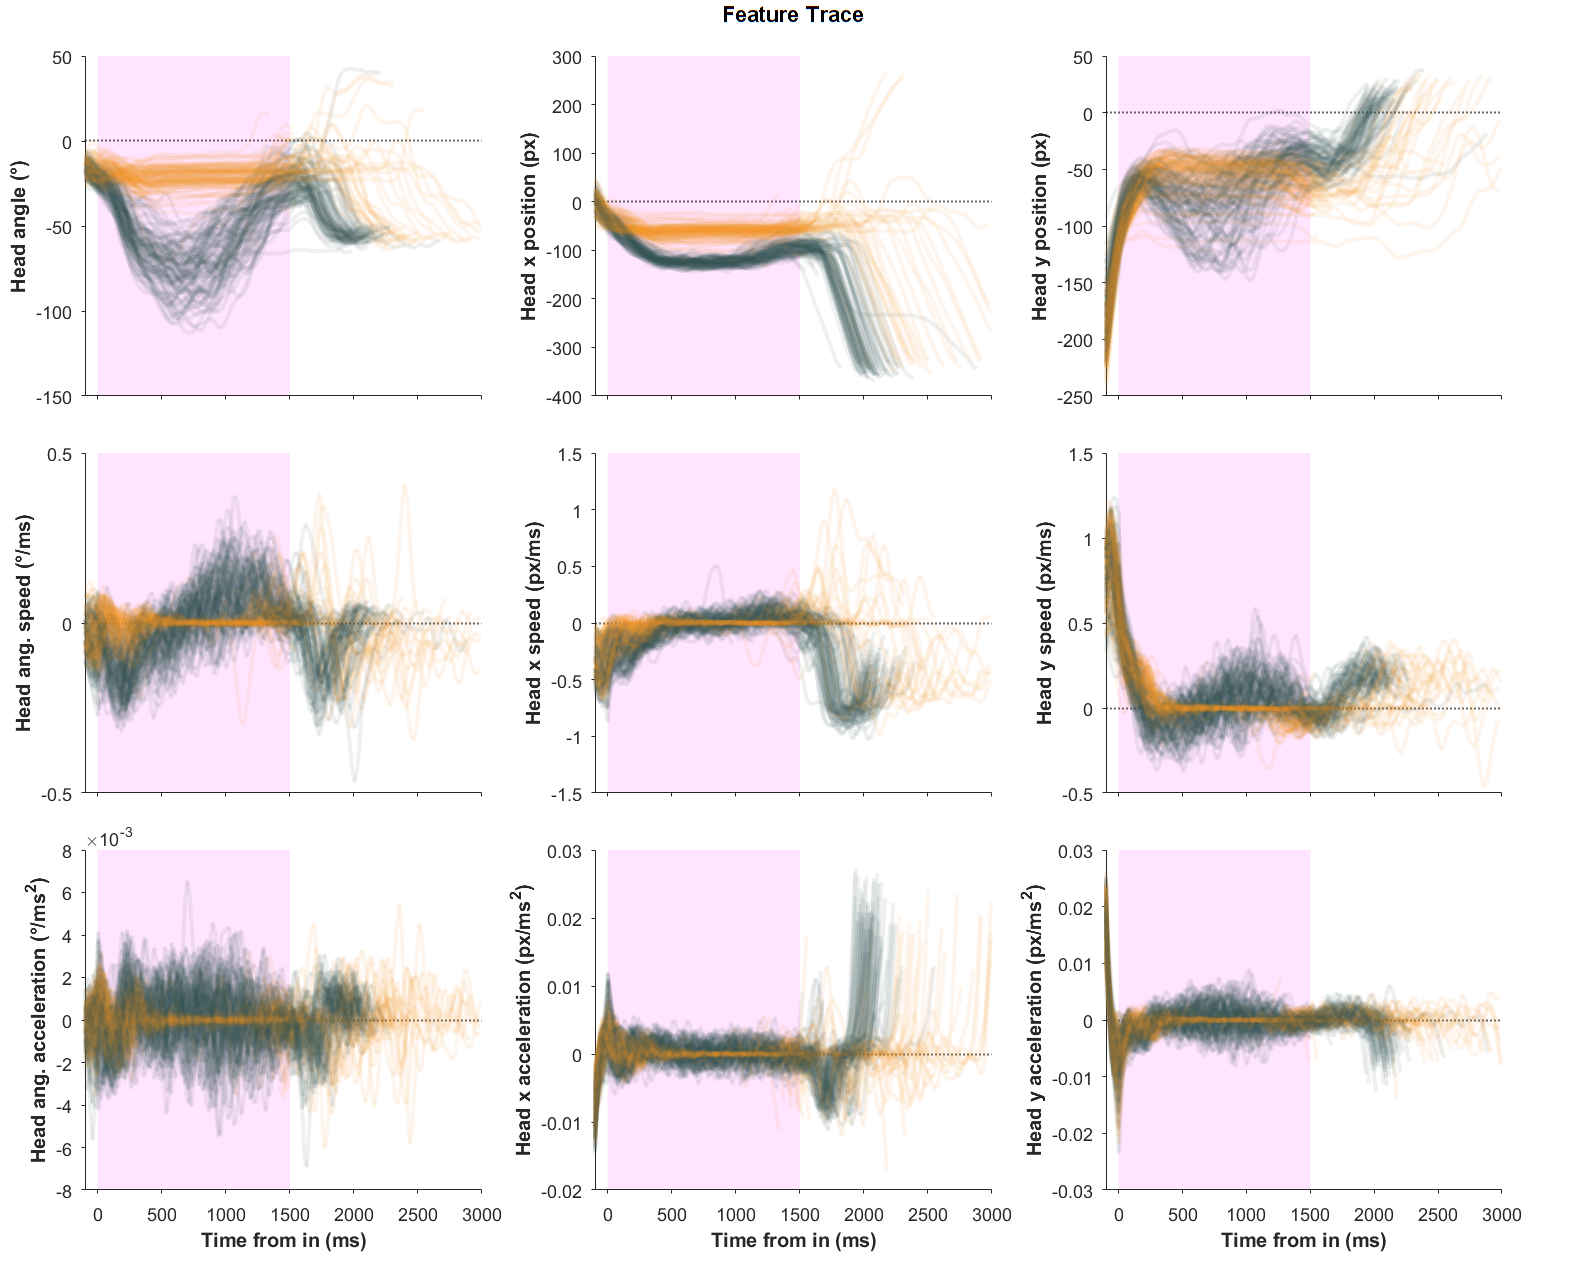

ax_size = [7 6];
ax_pos = [1.5 15.5; 1.5 8.5; 1.5 1.5; 10.5 15.5; 10.5 8.5; 10.5 1.5; 19.5 15.5; 19.5 8.5; 19.5 1.5];
for j = 1:2
    fig_trace_in = figure(51); clf(51);
    set(fig_trace_in, 'Units', 'Centimeters', 'Position', [1 1 28 22.5], 'PaperPositionMode', 'Auto', 'Color', 'w');

    uicontrol('Style', 'text', 'parent', fig_trace_in, 'units', 'normalized', 'position', [0.2 0.97 0.6 0.03],...
        'string', "Feature Trace", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

    w_now = 1.5; h_now = 20;
    for f = 1:length(Features)
        ax_back = axes;
        set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos(f, :) ax_size], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

        ax_front = axes;
        set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos(f, :) ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

        j_trials = [opts.trial_ctrl{j}(randperm(opts.num_ctrl(j), opts.num_show)); opts.trial_chemo{j}(randperm(opts.num_chemo(j), opts.num_show))];
        j_color = [opts.color_ctrl{j}(1:opts.num_show, :); opts.color_chemo{j}(1:opts.num_show, :)];
        j_shuffle = randperm(length(j_trials));

        for i = 1:length(j_trials)
            i_trial = j_trials(j_shuffle(i));
            i_color = j_color(j_shuffle(i), :);
            plot(ax_front, obj.TimeFromIn{i_trial}, obj.(Features(f)){i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
        end

        ax_front.XLim = obj.TimeMatIn([1 end]);
        ax_front.YLabel.String = FeatureLabels(f);
        ax_front.YLabel.FontWeight = "bold";

        if ~mod(f, 3)
            ax_front.XLabel.String = "Time from in (ms)";
            ax_front.XLabel.FontWeight = "bold";
        else
            ax_front.XTickLabel = [];
        end

        ax_back.XLim = ax_front.XLim;
        ax_back.YLim = ax_front.YLim;
        fill(ax_back, 1000*[0 obj.TaskFP obj.TaskFP 0], [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', 'FaceColor', 'm', 'FaceAlpha', .1, 'EdgeColor', 'none');
        yline(ax_back, 0, ':', 'LineWidth', 1);

    end

    save_name = "FeatureTraceIn_" + obj.Ports(j) + "_" + obj.ANM + "_" + obj.Task + ".jpg";
    save_path = fullfile(FigFolder, save_name);
    saveas(fig_trace_in, save_path);
end

## Plot trace of features (aligned to poke-out)

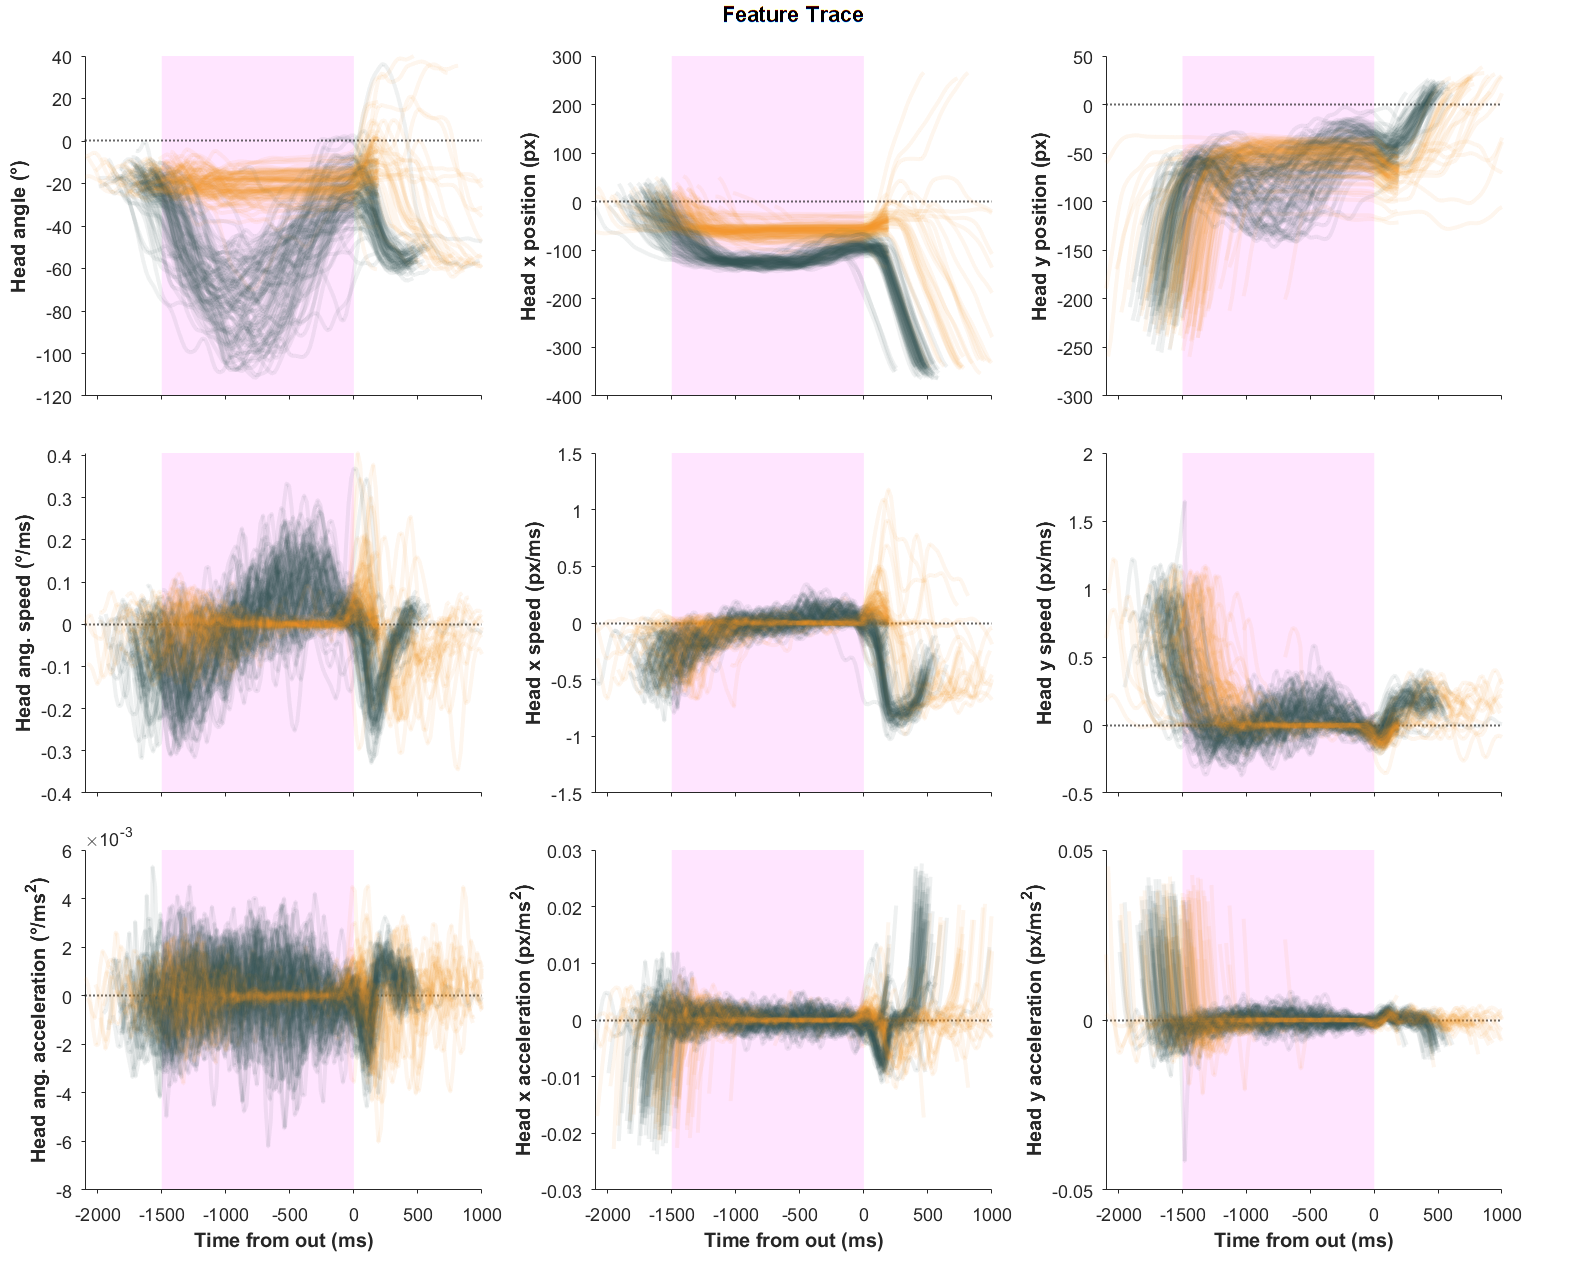

ax_size = [7 6];
ax_pos = [1.5 15.5; 1.5 8.5; 1.5 1.5; 10.5 15.5; 10.5 8.5; 10.5 1.5; 19.5 15.5; 19.5 8.5; 19.5 1.5];
for j = 1:2
    fig_trace_out = figure(52); clf(52);
    set(fig_trace_out, 'Units', 'Centimeters', 'Position', [1 1 28 22.5], 'PaperPositionMode', 'Auto', 'Color', 'w');

    uicontrol('Style', 'text', 'parent', fig_trace_out, 'units', 'normalized', 'position', [0.2 0.97 0.6 0.03],...
        'string', "Feature Trace", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

    w_now = 1.5; h_now = 20;
    for f = 1:length(Features)
        ax_back = axes;
        set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos(f, :) ax_size], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

        ax_front = axes;
        set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos(f, :) ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

        j_trials = [opts.trial_ctrl{j}(randperm(opts.num_ctrl(j), opts.num_show)); opts.trial_chemo{j}(randperm(opts.num_chemo(j), opts.num_show))];
        j_color = [opts.color_ctrl{j}(1:opts.num_show, :); opts.color_chemo{j}(1:opts.num_show, :)];
        j_shuffle = randperm(length(j_trials));

        for i = 1:length(j_trials)
            i_trial = j_trials(j_shuffle(i));
            i_color = j_color(j_shuffle(i), :);
            plot(ax_front, obj.TimeFromOut{i_trial}, obj.(Features(f)){i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
        end

        ax_front.XLim = obj.TimeMatOut([1 end]);
        ax_front.YLabel.String = FeatureLabels(f);
        ax_front.YLabel.FontWeight = "bold";

        if ~mod(f, 3)
            ax_front.XLabel.String = "Time from out (ms)";
            ax_front.XLabel.FontWeight = "bold";
        else
            ax_front.XTickLabel = [];
        end

        ax_back.XLim = ax_front.XLim;
        ax_back.YLim = ax_front.YLim;
        fill(ax_back, -1000*[0 obj.TaskFP obj.TaskFP 0], [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', 'FaceColor', 'm', 'FaceAlpha', .1, 'EdgeColor', 'none');
        yline(ax_back, 0, ':', 'LineWidth', 1);

    end

    save_name = "FeatureTraceOut_" + obj.Ports(j) + "_" + obj.ANM + "_" + obj.Task + ".jpg";
    save_path = fullfile(FigFolder, save_name);
    saveas(fig_trace_out, save_path);
end

## Plot trace of features (warped)

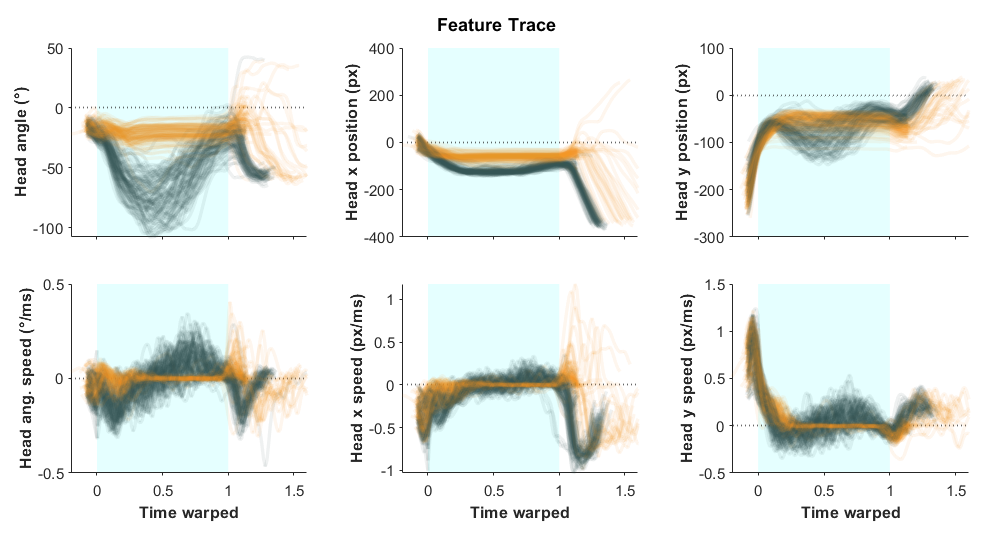

ax_size = [5 4];
ax_pos = [1.5 11.5; 1.5 6.5; 1.5 1.5; 8.5 11.5; 8.5 6.5; 8.5 1.5; 15.5 11.5; 15.5 6.5; 15.5 1.5];
for j = 1:2
    fig_trace_warp = figure(51); clf(51);
    set(fig_trace_warp, 'Units', 'Centimeters', 'Position', [1 1 21 16.5], 'PaperPositionMode', 'Auto', 'Color', 'w', 'visible', 'on');

    set_fig_title(fig_trace_warp, 'Feature Trace', 'FontSize', 11);

    for f = 1:length(Features)
        ax_back = axes;
        set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos(f, :) ax_size], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

        ax_front = axes;
        set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos(f, :) ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

        j_trials = [opts.trial_ctrl{j}(randperm(opts.num_ctrl(j), opts.num_show)); opts.trial_chemo{j}(randperm(opts.num_chemo(j), opts.num_show))];
        j_color = [opts.color_ctrl{j}(1:opts.num_show, :); opts.color_chemo{j}(1:opts.num_show, :)];
        j_shuffle = randperm(length(j_trials));

        for i = 1:length(j_trials)
            i_trial = j_trials(j_shuffle(i));
            i_color = j_color(j_shuffle(i), :);
            plot(ax_front, obj.TimeWarped{i_trial}, obj.(Features(f)){i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
        end

        ax_front.XLim = obj.TimeMatWarp([1 end]);
        ax_front.YLabel.String = FeatureLabels(f);
        ax_front.YLabel.FontWeight = "bold";

        if ~mod(f, 3)
            ax_front.XLabel.String = "Time warped";
            ax_front.XLabel.FontWeight = "bold";
        else
            ax_front.XTickLabel = [];
        end

        ax_back.XLim = ax_front.XLim;
        ax_back.YLim = ax_front.YLim;
        fill(ax_back, [0 1 1 0], [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', 'FaceColor', 'c', 'FaceAlpha', .1, 'EdgeColor', 'none');
        yline(ax_back, 0, ':', 'LineWidth', 1);

        drawnow();

    end

    save_name = "FeatureTraceWarp_" + obj.Ports(j) + "_" + obj.ANM + "_" + obj.Task + ".jpg";
    save_path = fullfile(FigFolder, save_name);
    exportgraphics(fig_trace_warp, save_path, 'Resolution', 600);
end

## Plot speed of head

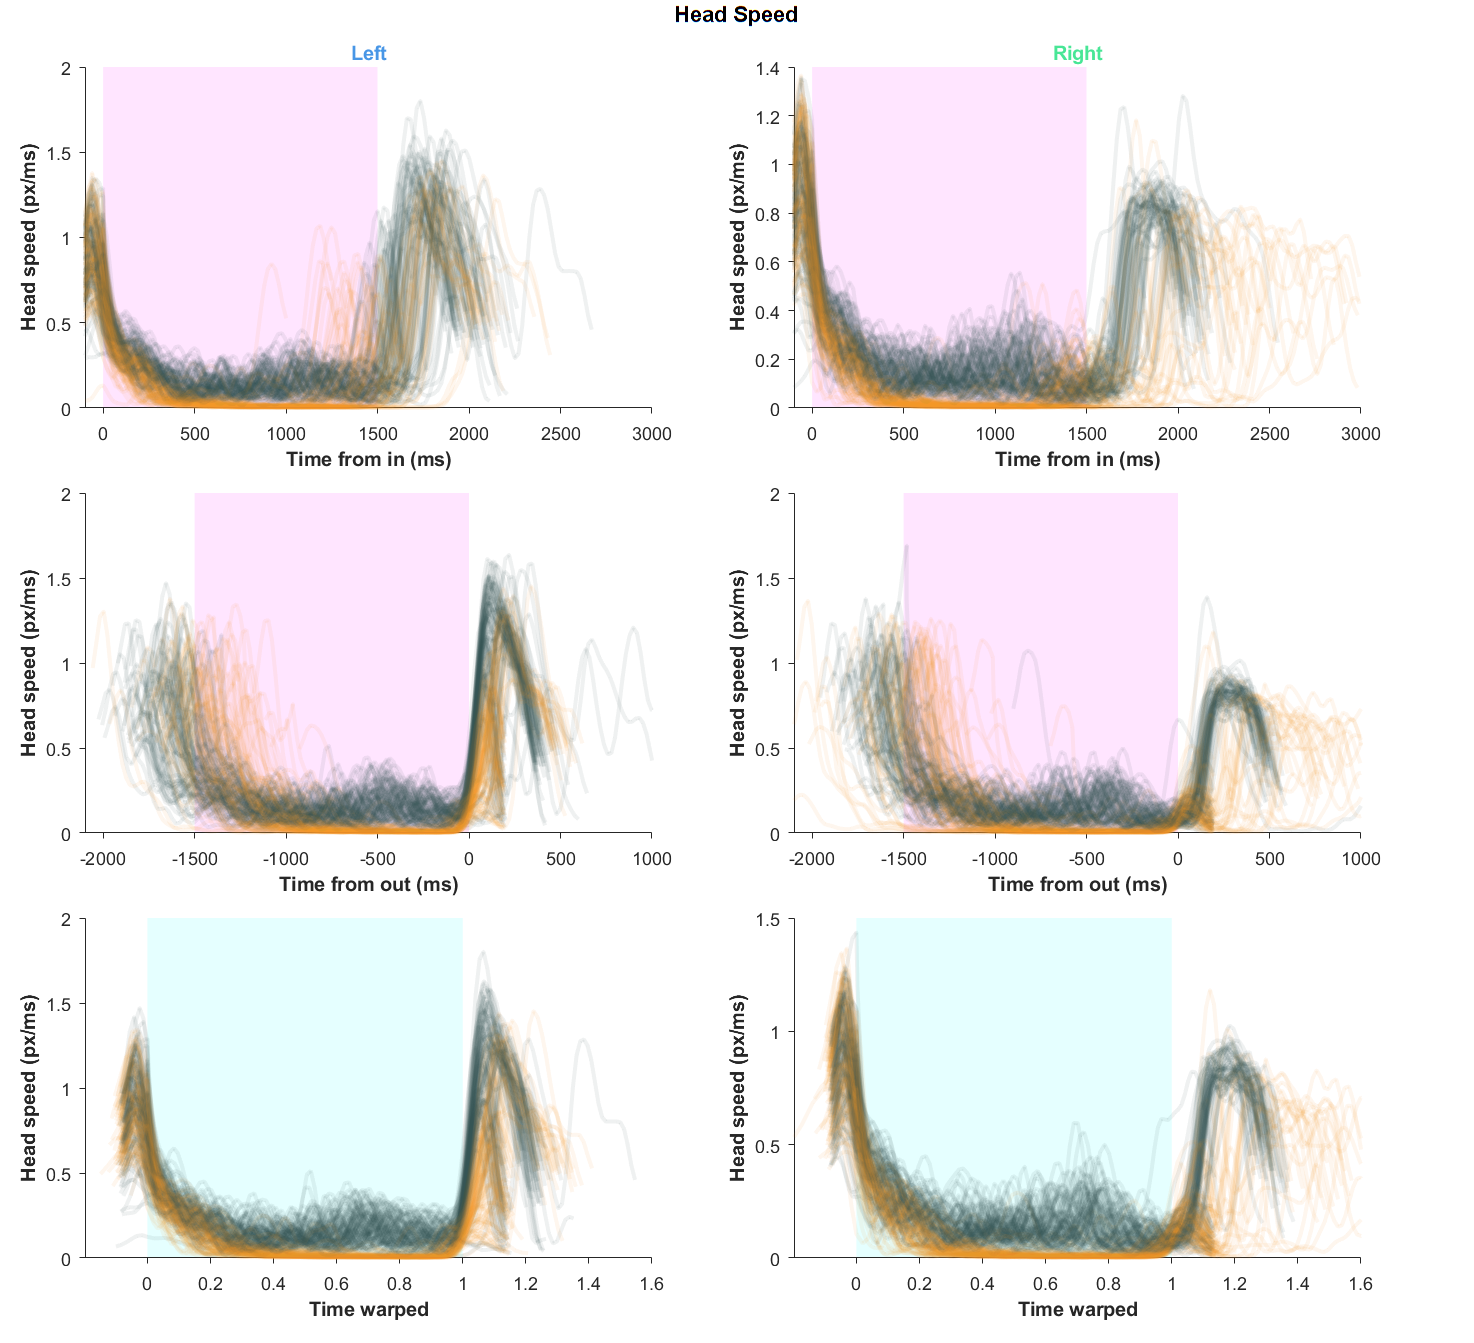

ax_size = [10 6];
ax_pos = [1.5 16.5; 1.5 9; 1.5 1.5; 14 16.5; 14 9; 14 1.5];

fig_speed = figure(54); clf(54);
set(fig_speed, 'Units', 'Centimeters', 'Position', [1 1 26 23.7], 'PaperPositionMode', 'Auto', 'Color', 'w');
uicontrol('Style', 'text', 'parent', fig_speed, 'units', 'normalized', 'position', [0.2 0.97 0.6 0.03],...
    'string', "Head Speed", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for j = 1:2

    for k = 1:3
        switch k
            case 1
                k_time_trace = obj.TimeFromIn;
                k_time_mat = obj.TimeMatIn;
                k_fill = 1000*[0 obj.TaskFP obj.TaskFP 0];
                k_fill_c = 'm';
                k_x_label = 'Time from in (ms)';
            case 2
                k_time_trace = obj.TimeFromOut;
                k_time_mat = obj.TimeMatOut;
                k_fill = -1000*[0 obj.TaskFP obj.TaskFP 0];
                k_fill_c = 'm';
                k_x_label = 'Time from out (ms)';
            case 3
                k_time_trace = obj.TimeWarped;
                k_time_mat = obj.TimeMatWarp;
                k_fill = [0 1 1 0];
                k_fill_c = 'c';
                k_x_label = 'Time warped';
        end
        ax_back = axes;
        set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos(k+j*3-3, :) ax_size], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

        ax_front = axes;
        set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos(k+j*3-3, :) ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

        j_trials = [opts.trial_ctrl{j}(randperm(opts.num_ctrl(j), opts.num_show)); opts.trial_chemo{j}(randperm(opts.num_chemo(j), opts.num_show))];
        j_color = [opts.color_ctrl{j}(1:opts.num_show, :); opts.color_chemo{j}(1:opts.num_show, :)];
        j_shuffle = randperm(length(j_trials));

        for i = 1:length(j_trials)
            i_trial = j_trials(j_shuffle(i));
            i_color = j_color(j_shuffle(i), :);
            plot(ax_front, k_time_trace{i_trial}, obj.SpeedHead{i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
        end

        ax_front.XLim = k_time_mat([1 end]);
        ax_front.YLabel.String = "Head speed (px/ms)";
        ax_front.YLabel.FontWeight = "bold";

        ax_front.XLabel.String = k_x_label;
        ax_front.XLabel.FontWeight = "bold";
        if k == 1
            switch j
                case 1
                    ax_front.Title.String = "Left";
                case 2
                    ax_front.Title.String = "Right";
            end
            ax_front.Title.FontWeight = "bold";
            ax_front.Title.Color = GPSColor.("Port"+obj.Ports(j));
        end

        ax_back.XLim = ax_front.XLim;
        ax_back.YLim = ax_front.YLim;
        fill(ax_back, k_fill, [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', 'FaceColor', k_fill_c, 'FaceAlpha', .1, 'EdgeColor', 'none');
%         yline(ax_back, 0, ':', 'LineWidth', 1);
    end
end
save_name = "SpeedTrace_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
saveas(fig_speed, save_path);

## PCA for features

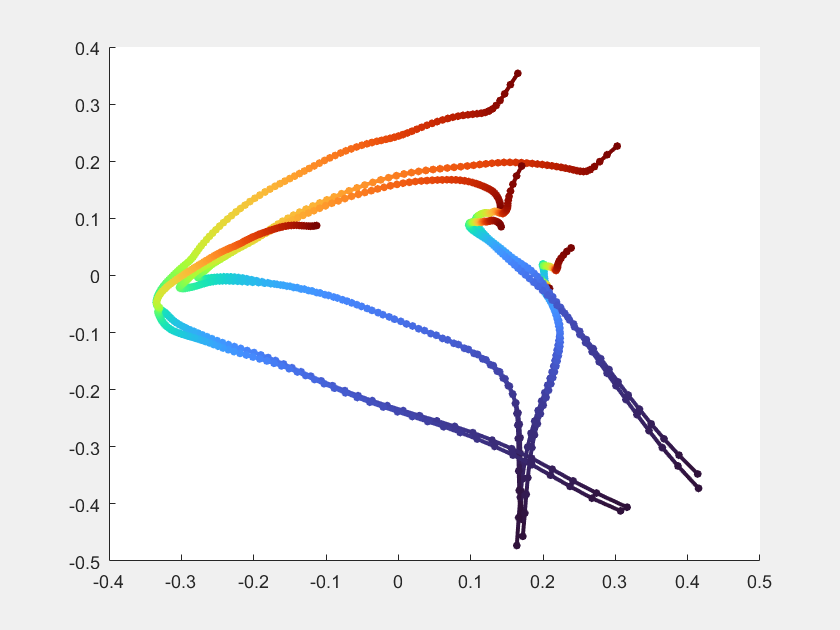

MatWarpAlign = obj.trace2mat(TraceGathered, obj.TimeWarped, obj.TimeWarpAlign);
[TraceWarpAlign, TimeTraceWarpAlign] = obj.mat2trace(MatWarpAlign, obj.TimeWarpAlign);
ArrayWarpAlign = obj.trace2array(TraceWarpAlign);
ArrayWarpAlign_n = normalize(ArrayWarpAlign, 1, 'range');

[coeffPCA, ArrayWarpAlignPCA, latentPCA, tsquarePCA, explainedPCA, muPCA] = pca(ArrayWarpAlign_n);
n_dim = find(cumsum(explainedPCA)>95, 1);

TraceWarpAlignPCA = obj.array2trace(ArrayWarpAlignPCA, TimeTraceWarpAlign);
MatWarpAlignPCA = obj.trace2mat(TraceWarpAlignPCA, TimeTraceWarpAlign, obj.TimeWarpAlign);

figure('Visible', 'on'); hold on;
colormap('turbo');

for j = 1:2

MatWarpAlignCtrl_j = squeeze(mean(MatWarpAlignPCA(opts.trial_ctrl{j}, :, :), 1));
MatWarpAlignChemo_j = squeeze(mean(MatWarpAlignPCA(opts.trial_chemo{j}, :, :), 1));

patch([MatWarpAlignCtrl_j(:, 1); nan], [MatWarpAlignCtrl_j(:, 2); nan], [linspace(0, 1, length(obj.TimeWarpAlign)) nan], ...
    'EdgeColor', 'interp', 'LineWidth', 2, 'Marker', 'o', 'MarkerFaceColor', 'flat', 'MarkerSize', 2);
patch([MatWarpAlignChemo_j(:, 1); nan], [MatWarpAlignChemo_j(:, 2); nan], [linspace(0, 1, length(obj.TimeWarpAlign)) nan], ...
    'EdgeColor', 'interp', 'LineWidth', 2, 'Marker', 'o', 'MarkerFaceColor', 'flat', 'MarkerSize', 2);
end

% 
% % view(gca, 0, 30)


## Plot distance matrix

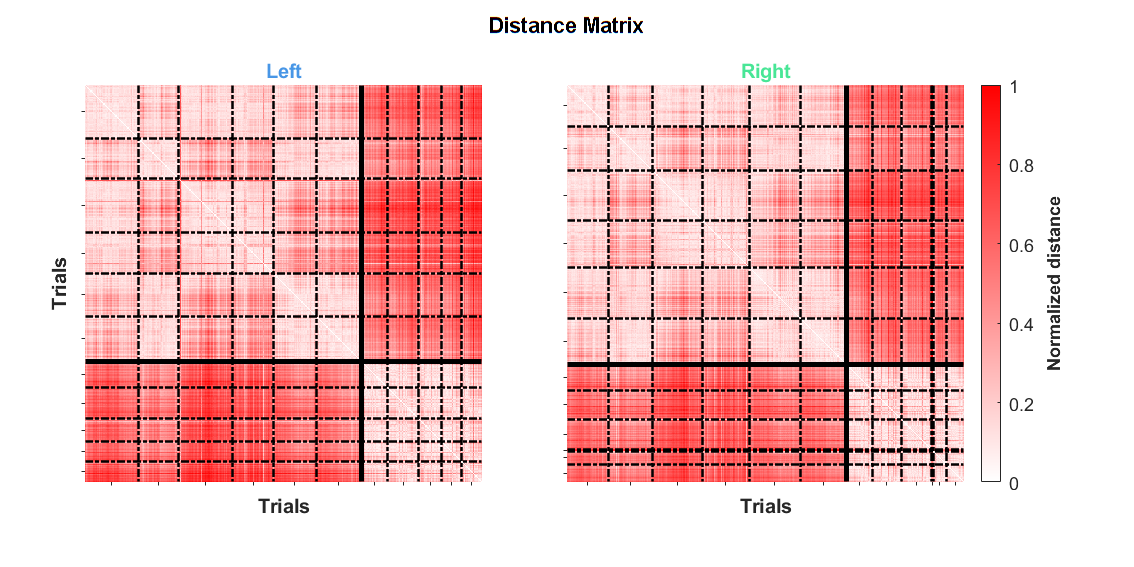

mycolormap = customcolormap([0 1], [1 0 0; 1 1 1]);

fig_dist = figure(55); clf(55);
set(fig_dist, 'Units', 'Centimeters', 'Position', [1 1 20 10], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_dist, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "Distance Matrix", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for j = 1:2

    ax_dist = axes;
    set(ax_dist, 'Units', 'Centimeters', 'Position', [1.5+8.5*(j-1) 1.5 7 7], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YDir', 'reverse');
    colormap(mycolormap);

    j_trials = [opts.trial_ctrl{j}; opts.trial_chemo{j}];
    j_DistM = obj.DistMatDtw(opts.trial{j}, opts.trial{j});
    j_DistM = normalize(j_DistM(:), 'range');
    j_DistM = reshape(j_DistM, opts.num_trial(j), opts.num_trial(j));

    imagesc(j_DistM); clim([0 1]);

    j_seps = [opts.session_sep_ctrl{j}; opts.session_sep_ctrl{j}(end)+opts.session_sep_chemo{j}] + 0.5;

    xline(j_seps(1:end-1), 'LineStyle', '-.', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);
    yline(j_seps(1:end-1), 'LineStyle', '-.', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);

    xline(opts.num_ctrl(j)+0.5, 'LineStyle', '-', 'LineWidth', 2.5, 'Color', 'k', 'Alpha', 1);
    yline(opts.num_ctrl(j)+0.5, 'LineStyle', '-', 'LineWidth', 2.5, 'Color', 'k', 'Alpha', 1);

    xlim([.5 length(j_trials)+.5]);
    ylim([.5 length(j_trials)+.5]);

    xticks(j_seps - [opts.session_num_ctrl{j}; opts.session_num_chemo{j}] / 2); xticklabels([]);
    yticks(j_seps - [opts.session_num_ctrl{j}; opts.session_num_chemo{j}] / 2); yticklabels([]);

    if j == 1
        ax_dist.YLabel.String = "Trials";
        ax_dist.YLabel.FontWeight = "Bold";
    end
    ax_dist.XLabel.String = "Trials";
    ax_dist.XLabel.FontWeight = "Bold";

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_dist, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');

end

ax_cb = axes;
set(ax_cb, 'Units', 'Centimeters', 'Position', [13.5 1.5 5 7], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', ...
    'Color', 'none', 'XColor', 'none', 'YColor', 'none');
cb = colorbar;
clim(ax_cb, [0 1]);
cb.FontSize = 9;
cb.Label.String = "Normalized distance";
cb.Label.FontSize = 9;
cb.Label.FontWeight = 'bold';


% save_name = "DistDtwMatrix_" + obj.ANM + "_" + obj.Task + ".jpg";
% save_path = fullfile(FigFolder, save_name);
% saveas(fig_dist, save_path);


## MDS

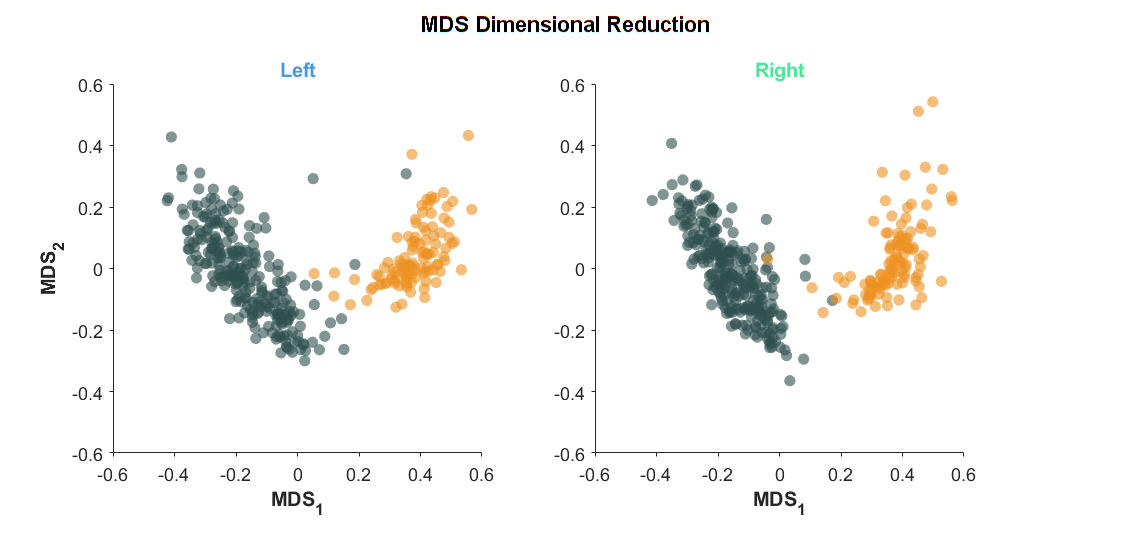

MDSScore = cell(1, 2);
MDSCost  = cell(1, 2);

fig_mds = figure(56); clf(56);
set(fig_mds, 'Units', 'Centimeters', 'Position', [1 1 20 9.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
uicontrol('Style', 'text', 'parent', fig_mds, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "MDS Dimensional Reduction", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for j = 1:2

    j_DistM = obj.DistMatDtw(opts.trial{j}, opts.trial{j});
    j_DistM = normalize(j_DistM(:), 'range');
    j_DistM = reshape(j_DistM, opts.num_trial(j), opts.num_trial(j));

    [MDSScore{j}, MDSCost{j}] = cmdscale(j_DistM);
    
    ax_mds = axes;
    set(ax_mds, 'Units', 'Centimeters', 'Position', [2+8.5*(j-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    j_shuffle = randperm(opts.num_trial(j));
    scatter(ax_mds, MDSScore{j}(j_shuffle,1), MDSScore{j}(j_shuffle,2), 32, opts.color_trial{j}(j_shuffle,:), "filled", 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'none');

    if j == 1
        ax_mds.YLabel.String = "MDS_2";
        ax_mds.YLabel.FontWeight = "Bold";
    end
    ax_mds.XLabel.String = "MDS_1";
    ax_mds.XLabel.FontWeight = "Bold";

    ax_mds.YLim = ax_mds.XLim;

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_mds, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');
end


% save_name = "MDS_" + obj.ANM + "_" + obj.Task + ".jpg";
% save_path = fullfile(FigFolder, save_name);
% saveas(fig_mds, save_path);


## t-SNE

tSNEScore = cell(1, 2);

fig_tsne = figure(57); clf(57);
set(fig_tsne, 'Units', 'Centimeters', 'Position', [1 1 20 9.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
uicontrol('Style', 'text', 'parent', fig_tsne, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "t-SNE Dimensional Reduction", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for j = 1:2

    j_DistM = obj.DistMatDtw(opts.trial{j}, opts.trial{j});
    j_DistM = normalize(j_DistM(:), 'range');
    j_DistM = reshape(j_DistM, opts.num_trial(j), opts.num_trial(j));

    tSNEScore{j} = tsne_d(j_DistM);
    
    ax_tsne = axes;
    set(ax_tsne, 'Units', 'Centimeters', 'Position', [2+8.5*(j-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    j_shuffle = randperm(opts.num_trial(j));
    scatter(ax_tsne, tSNEScore{j}(j_shuffle,1), tSNEScore{j}(j_shuffle,2), 32, opts.color_trial{j}(j_shuffle,:), "filled", 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'none');

    if j == 1
        ax_tsne.YLabel.String = "t-SNE_2";
        ax_tsne.YLabel.FontWeight = "Bold";
    end
    ax_tsne.XLabel.String = "t-SNE_1";
    ax_tsne.XLabel.FontWeight = "Bold";

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_tsne, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');
end

Mean value of sigma: 0.014927
Minimum value of sigma: 0.0074065
Maximum value of sigma: 0.08839
Mean value of sigma: 0.018598
Minimum value of sigma: 0.0084194
Maximum value of sigma: 0.08149


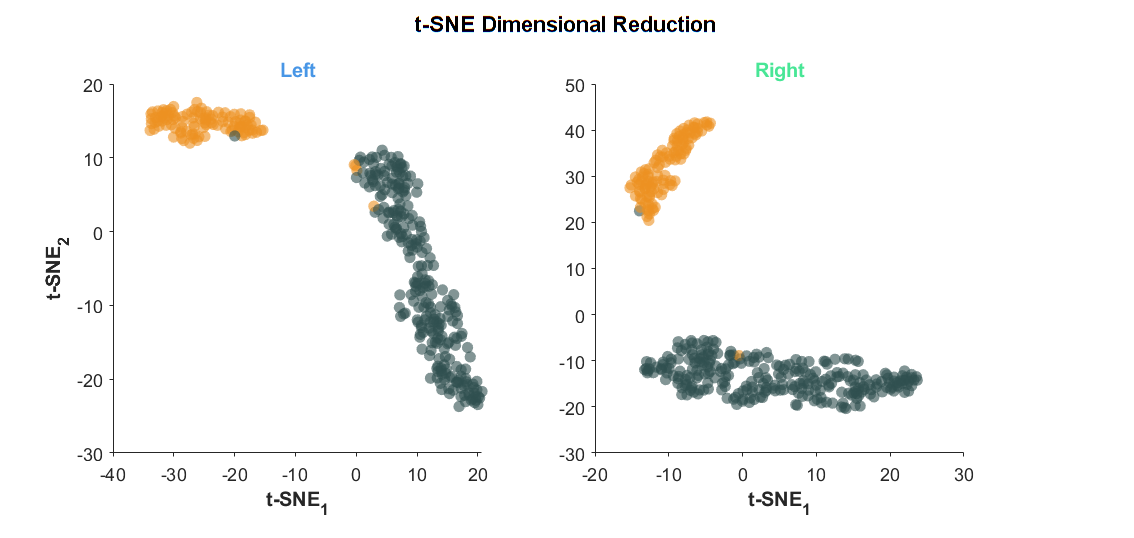


save_name = "tSNE_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
saveas(fig_tsne, save_path);

# Predict hold phase using movement features

## Entire holding period ([0 1])

### loss function

r_square = @(y, y_fit, ~) 1 - sum((y-y_fit).^2)/sum((y-mean(y)).^2);
var_explained = @(y, y_fit, ~) 1 - var(y-y_fit)/var(y);


### preprocess data

time_bins = 0:0.05:1;
TraceHold = cellfun(@(trace, t) trace(t>=0 & t<=1, :), TraceGathered, obj.TimeWarped, 'UniformOutput', false);
PhaseHold = cellfun(@(t) t(t>=0 & t<=1), obj.TimeWarped, 'UniformOutput', false);

ArrayHoldCtrl = cell(1, 2);
ArrayHoldChemo = cell(1, 2);
ArrayHoldCtrl_n = cell(1, 2);
ArrayHoldChemo_n = cell(1, 2);

PhaseHoldCtrl = cell(1, 2);
PhaseHoldChemo = cell(1, 2);

for j = 1:2
    j_shuffle_ctrl = randperm(opts.num_ctrl(j), opts.num_size);
    j_shuffle_chemo = randperm(opts.num_chemo(j), opts.num_size);

    ArrayHoldCtrl{j} = cell2mat(TraceHold(opts.trial_ctrl{j}(j_shuffle_ctrl))');
    ArrayHoldChemo{j} = cell2mat(TraceHold(opts.trial_chemo{j}(j_shuffle_chemo))');

    ArrayHoldCtrl_n{j} = normalize(ArrayHoldCtrl{j}, 1, "range");
    ArrayHoldChemo_n{j} = normalize(ArrayHoldChemo{j}, 1, "range");

    PhaseHoldCtrl{j} = cell2mat(PhaseHold(opts.trial_ctrl{j}(j_shuffle_ctrl))');
    PhaseHoldChemo{j} = cell2mat(PhaseHold(opts.trial_chemo{j}(j_shuffle_chemo))');
end


### Linear model


MdlHoldCtrl_linear = cell(1, 2);
MdlHoldChemo_linear = cell(1, 2);

fig_linear = figure(58); clf(58);
set(fig_linear, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
uicontrol('Style', 'text', 'parent', fig_linear, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
    'string', "Linear model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);

for j = 1:2
    MdlHoldCtrl_linear{j} = fitrlinear(ArrayHoldCtrl_n{j}, PhaseHoldCtrl{j}, 'KFold', 10);
    MdlHoldChemo_linear{j} = fitrlinear(ArrayHoldChemo_n{j}, PhaseHoldChemo{j}, 'KFold', 10);

    ax_ctrl = axes;
    set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(j-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_ctrl = kfoldPredict(MdlHoldCtrl_linear{j});
    %     scatter(MdlHoldCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
    y_fit_ctrl_prob = histcounts2(MdlHoldCtrl_linear{j}.Y, y_fit_ctrl, time_bins, time_bins);
    y_fit_ctrl_prob = y_fit_ctrl_prob';
    y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);

    imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);

    ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_ctrl.YLim = ax_ctrl.XLim;
    ax_ctrl.XTick = 0:5:20;
    ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
    ax_ctrl.YTick = ax_ctrl.XTick;
    ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');

    ax_chemo = axes;
    set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(j-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_chemo = kfoldPredict(MdlHoldChemo_linear{j});
    y_fit_chemo_prob = histcounts2(MdlHoldChemo_linear{j}.Y, y_fit_chemo, time_bins, time_bins);
    y_fit_chemo_prob = y_fit_chemo_prob';
    y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);

    imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);

    ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_chemo.YLim = ax_chemo.XLim;
    ax_chemo.XTick = 0:5:20;
    ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
    ax_chemo.YTick = ax_chemo.XTick;
    ax_chemo.YTickLabel = ax_chemo.XTickLabel;

    ax_chemo.XLabel.String = "Hold phase";
    ax_chemo.XLabel.FontWeight = "bold";

    if j == 2
        cb.Label.String = "Predict probability";
        cb.Label.FontSize = 11;
        cb.Label.FontWeight = "bold";
    end

    if j == 1
        ax_ctrl.YLabel.String = "Predicted phase Ctrl";
        ax_ctrl.YLabel.FontWeight = "bold";
        ax_ctrl.YLabel.Color = GPSColor.Control;
        ax_chemo.YLabel.String = "Predicted phase Chemo";
        ax_chemo.YLabel.FontWeight = "bold";
        ax_chemo.YLabel.Color = GPSColor.Treat;
    end
end

save_name = "MdlHold_linear_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
saveas(fig_linear, save_path);


### Neural network model

MdlHoldCtrl_nn = cell(1, 2);
MdlHoldChemo_nn = cell(1, 2);

fig_nn = figure(60); clf(60);
set(fig_nn, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
uicontrol('Style', 'text', 'parent', fig_nn, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
    'string', "Neural network model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);

for j = 1:2
    MdlHoldCtrl_nn{j} = fitrnet(ArrayHoldCtrl_n{j}, PhaseHoldCtrl{j}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);
    MdlHoldChemo_nn{j} = fitrnet(ArrayHoldChemo_n{j}, PhaseHoldChemo{j}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);

    ax_ctrl = axes;
    set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(j-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_ctrl = kfoldPredict(MdlHoldCtrl_nn{j});
    %     scatter(MdlHoldCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
    y_fit_ctrl_prob = histcounts2(MdlHoldCtrl_nn{j}.Y, y_fit_ctrl, time_bins, time_bins);
    y_fit_ctrl_prob = y_fit_ctrl_prob';
    y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);

    imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);

    ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_ctrl.YLim = ax_ctrl.XLim;
    ax_ctrl.XTick = 0:5:20;
    ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
    ax_ctrl.YTick = ax_ctrl.XTick;
    ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');

    ax_chemo = axes;
    set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(j-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_chemo = kfoldPredict(MdlHoldChemo_nn{j});
    y_fit_chemo_prob = histcounts2(MdlHoldChemo_nn{j}.Y, y_fit_chemo, time_bins, time_bins);
    y_fit_chemo_prob = y_fit_chemo_prob';
    y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);

    imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);

    ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_chemo.YLim = ax_chemo.XLim;
    ax_chemo.XTick = 0:5:20;
    ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
    ax_chemo.YTick = ax_chemo.XTick;
    ax_chemo.YTickLabel = ax_chemo.XTickLabel;

    ax_chemo.XLabel.String = "Hold phase";
    ax_chemo.XLabel.FontWeight = "bold";

    if j == 2
        cb.Label.String = "Predict probability";
        cb.Label.FontSize = 11;
        cb.Label.FontWeight = "bold";
    end

    if j == 1
        ax_ctrl.YLabel.String = "Predicted phase Ctrl";
        ax_ctrl.YLabel.FontWeight = "bold";
        ax_ctrl.YLabel.Color = GPSColor.Control;
        ax_chemo.YLabel.String = "Predicted phase Chemo";
        ax_chemo.YLabel.FontWeight = "bold";
        ax_chemo.YLabel.Color = GPSColor.Treat;
    end
end

save_name = "MdlHold_nn_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
saveas(fig_nn, save_path);


## Trimmed holding period ([.1 .9])

### preprocess data

TraceTrim = cellfun(@(trace, t) trace(t>=.1 & t<=.9, :), TraceGathered, obj.TimeWarped, 'UniformOutput', false);
PhaseTrim = cellfun(@(t) t(t>=.1 & t<=.9), obj.TimeWarped, 'UniformOutput', false);

ArrayTrimCtrl = cell(1, 2);
ArrayTrimChemo = cell(1, 2);
ArrayTrimCtrl_n = cell(1, 2);
ArrayTrimChemo_n = cell(1, 2);

PhaseTrimCtrl = cell(1, 2);
PhaseTrimChemo = cell(1, 2);

for j = 1:2
    j_shuffle_ctrl = randperm(opts.num_ctrl(j), opts.num_size);
    j_shuffle_chemo = randperm(opts.num_chemo(j), opts.num_size);

    ArrayTrimCtrl{j} = cell2mat(TraceTrim(opts.trial_ctrl{j}(j_shuffle_ctrl))');
    ArrayTrimChemo{j} = cell2mat(TraceTrim(opts.trial_chemo{j}(j_shuffle_chemo))');

    ArrayTrimCtrl_n{j} = normalize(ArrayTrimCtrl{j}, 1, "range");
    ArrayTrimChemo_n{j} = normalize(ArrayTrimChemo{j}, 1, "range");

    PhaseTrimCtrl{j} = cell2mat(PhaseTrim(opts.trial_ctrl{j}(j_shuffle_ctrl))');
    PhaseTrimChemo{j} = cell2mat(PhaseTrim(opts.trial_chemo{j}(j_shuffle_chemo))');
end


### Linear model


MdlTrimCtrl_linear = cell(1, 2);
MdlTrimChemo_linear = cell(1, 2);

fig_linear = figure(58); clf(58);
set(fig_linear, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
uicontrol('Style', 'text', 'parent', fig_linear, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
    'string', "Linear model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);

for j = 1:2
    MdlTrimCtrl_linear{j} = fitrlinear(ArrayTrimCtrl_n{j}, PhaseTrimCtrl{j}, 'KFold', 10);
    MdlTrimChemo_linear{j} = fitrlinear(ArrayTrimChemo_n{j}, PhaseTrimChemo{j}, 'KFold', 10);

    ax_ctrl = axes;
    set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(j-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_ctrl = kfoldPredict(MdlTrimCtrl_linear{j});
    %     scatter(MdlTrimCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
    y_fit_ctrl_prob = histcounts2(MdlTrimCtrl_linear{j}.Y, y_fit_ctrl, time_bins, time_bins);
    y_fit_ctrl_prob = y_fit_ctrl_prob';w
    y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);

    imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);

    ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_ctrl.YLim = ax_ctrl.XLim;
    ax_ctrl.XTick = 0:5:20;
    ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
    ax_ctrl.YTick = ax_ctrl.XTick;
    ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');

    ax_chemo = axes;
    set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(j-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_chemo = kfoldPredict(MdlTrimChemo_linear{j});
    y_fit_chemo_prob = histcounts2(MdlTrimChemo_linear{j}.Y, y_fit_chemo, time_bins, time_bins);
    y_fit_chemo_prob = y_fit_chemo_prob';
    y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);

    imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);

    ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_chemo.YLim = ax_chemo.XLim;
    ax_chemo.XTick = 0:5:20;
    ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
    ax_chemo.YTick = ax_chemo.XTick;
    ax_chemo.YTickLabel = ax_chemo.XTickLabel;

    ax_chemo.XLabel.String = "Hold phase";
    ax_chemo.XLabel.FontWeight = "bold";

    if j == 2
        cb.Label.String = "Predict probability";
        cb.Label.FontSize = 11;
        cb.Label.FontWeight = "bold";
    end

    if j == 1
        ax_ctrl.YLabel.String = "Predicted phase Ctrl";
        ax_ctrl.YLabel.FontWeight = "bold";
        ax_ctrl.YLabel.Color = GPSColor.Control;
        ax_chemo.YLabel.String = "Predicted phase Chemo";
        ax_chemo.YLabel.FontWeight = "bold";
        ax_chemo.YLabel.Color = GPSColor.Treat;
    end
end

save_name = "MdlTrim_linear_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
saveas(fig_linear, save_path);


### Neural network model

MdlTrimCtrl_nn = cell(1, 2);
MdlTrimChemo_nn = cell(1, 2);

fig_nn = figure(60); clf(60);
set(fig_nn, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
uicontrol('Style', 'text', 'parent', fig_nn, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
    'string', "Neural network model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);

for j = 1:2
    MdlTrimCtrl_nn{j} = fitrnet(ArrayTrimCtrl_n{j}, PhaseTrimCtrl{j}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);
    MdlTrimChemo_nn{j} = fitrnet(ArrayTrimChemo_n{j}, PhaseTrimChemo{j}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);

    ax_ctrl = axes;
    set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(j-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_ctrl = kfoldPredict(MdlTrimCtrl_nn{j});
    %     scatter(MdlTrimCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
    y_fit_ctrl_prob = histcounts2(MdlTrimCtrl_nn{j}.Y, y_fit_ctrl, time_bins, time_bins);
    y_fit_ctrl_prob = y_fit_ctrl_prob';
    y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);

    imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);

    ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_ctrl.YLim = ax_ctrl.XLim;
    ax_ctrl.XTick = 0:5:20;
    ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
    ax_ctrl.YTick = ax_ctrl.XTick;
    ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');

    ax_chemo = axes;
    set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(j-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_chemo = kfoldPredict(MdlTrimChemo_nn{j});
    y_fit_chemo_prob = histcounts2(MdlTrimChemo_nn{j}.Y, y_fit_chemo, time_bins, time_bins);
    y_fit_chemo_prob = y_fit_chemo_prob';
    y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);

    imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);

    ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_chemo.YLim = ax_chemo.XLim;
    ax_chemo.XTick = 0:5:20;
    ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
    ax_chemo.YTick = ax_chemo.XTick;
    ax_chemo.YTickLabel = ax_chemo.XTickLabel;

    ax_chemo.XLabel.String = "Hold phase";
    ax_chemo.XLabel.FontWeight = "bold";

    if j == 2
        cb.Label.String = "Predict probability";
        cb.Label.FontSize = 11;
        cb.Label.FontWeight = "bold";
    end

    if j == 1
        ax_ctrl.YLabel.String = "Predicted phase Ctrl";
        ax_ctrl.YLabel.FontWeight = "bold";
        ax_ctrl.YLabel.Color = GPSColor.Control;
        ax_chemo.YLabel.String = "Predicted phase Chemo";
        ax_chemo.YLabel.FontWeight = "bold";
        ax_chemo.YLabel.Color = GPSColor.Treat;
    end
end

save_name = "MdlTrim_nn_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
saveas(fig_nn, save_path);
